# **Vehicle Performance Analysis (CoDPAD M1-2)**

CoDPAD module 1-2 : Vehicle performance analysis - Basic vehicle characteristics analysis

본 장에서는, CoDPAD M1.1에서 얻어진 기초데이터를 바탕으로 기체의 제어성능을 대표할 수 있는 지표를 산출하고 제시한다. TF로부터 얻을 수 있는 step response와 frequency response 결과를 9개의 state에 대해 산출한다. 그 후 회전익 기체의 성능을 대표할 수 있는 수치를 축약해 제시하며, 마지막으로 기체의 상태유지성능 (hovering, cruising)시의 state 유지 성능과 오차 추세에 대한 결과를 제시한다.

[CoDPAD Ch1.1 - Confluence](https://nearth.atlassian.net/l/c/jtPt190P)

[CoDPAD Ch. 1.2 - Confluence](https://nearth.atlassian.net/l/c/3fbf1ss9)

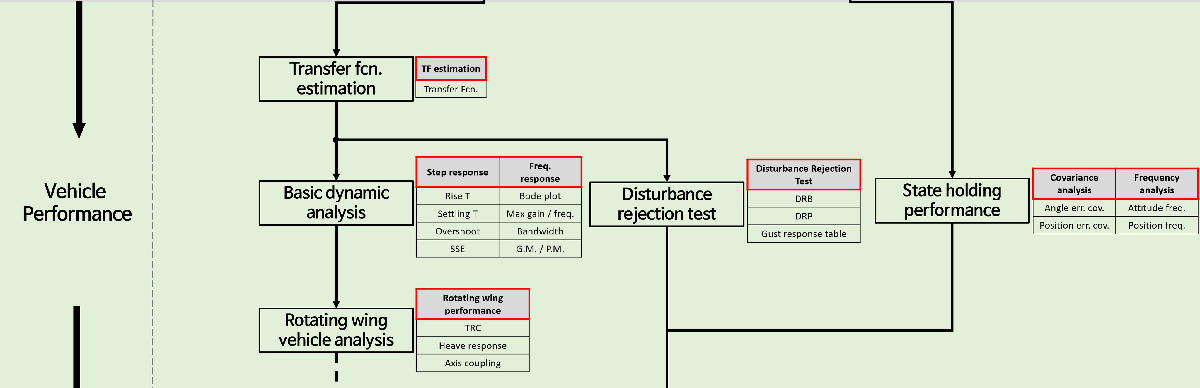

cd(fileparts(matlab.desktop.editor.getActiveFilename))
global calcDensity

## User Input

**index guide**

1 : roll rate (p)

2 : pitch rate (q)

3 : yaw rate (r)

4 : Roll angle ($\phi$)

5 : Pitch angle ($\theta$)

6 : Yaw angle ($\psi$)

7 : u

8 : v

9 : w

10: X

11: Y

12: Z

13: gimbal Roll

14: gimbal Pitch

15: gimbal Yaw

dataTypeToRefer = 0

dataTypeToRefer = 0

tfFile = load("tfResult.mat")

tfFile = struct with fields:
    tfResult: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}


heaveTfResult = load("heaveTf.mat")

heaveTfResult = struct with fields:
    heaveTfResult: [1×1 struct]


covResult = load("covResult.mat")

covResult = struct with fields:
    covResult: [1×1 struct]


covSampleNum = 10000

covSampleNum = 10000

confidence = 0.9

confidence = 0.9000

calcDensity = 300

calcDensity = 300

covResult = covResult.covResult;
heaveTfResult = heaveTfResult.heaveTfResult;
tfTemp = tfFile.tfResult;

isSweep = dataTypeToRefer;
if isSweep
    if isSweep == 1
        tfTemp(1:9) = [];
    end
end

tfData{1} = tfTemp{1};
tfData{2} = tfTemp{4};
tfData{3} = tfTemp{7};
tfData{4} = tfTemp{2};
tfData{5} = tfTemp{5};
tfData{6} = tfTemp{8};
tfData{7} = tfTemp{3};
tfData{8} = tfTemp{6};
tfData{9} = tfTemp{9};

dataSize = size(tfData,2);
dataName = {'Roll','Pitch','Yaw','u','v','w','X','Y','Z'};

## Basic Dynamic Characteristic Analysis

This part calculates basic dynamic characteristics from the transfer functions estimated at the previous chapter. Basic dynamic characteristics include step response (rise time, settling time, overshoot, peak gain and SSE (Steady State Error)) and frequency response (gain margin, phase margin). 

stepResult = {}; phaseResult = {};

#### Step response

Step response of transfer functions estimated from previous section is shown below.

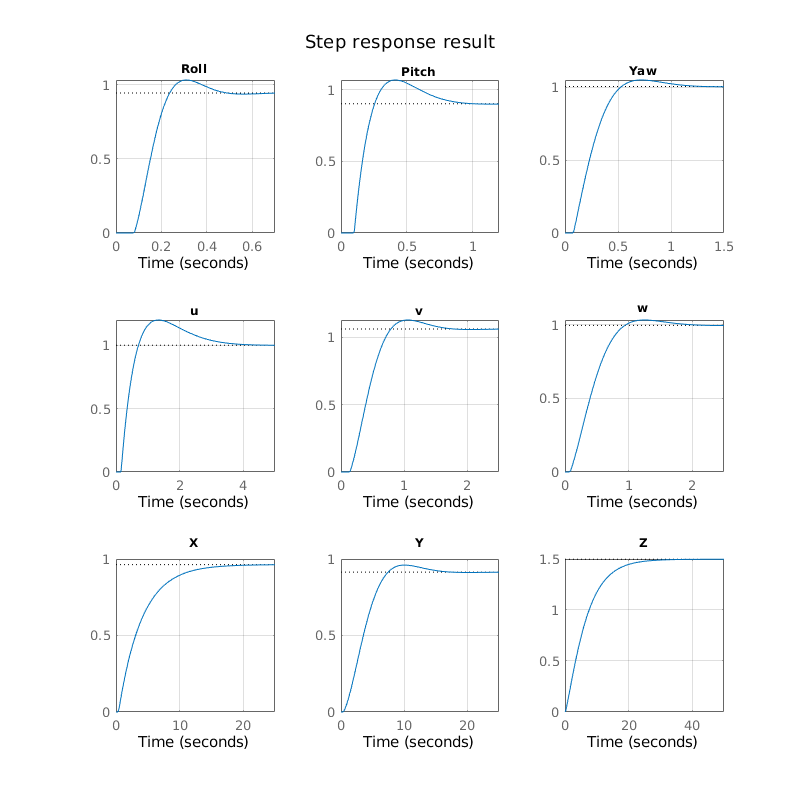

figure(9)
clf
set(gcf,'Position',[10 10 800 800])
for i = 1:dataSize
    sys = tf(tfData{i}.Num,tfData{i}.Den,'ioDelay',tfData{i}.Delay);
    stepResult{i} = stepinfo(sys);
    [gm,pm,wg,wp] = margin(sys);
    phaseResult{i} = [gm,pm,wg,wp,bandwidth(sys)];
    subplot(3,3,i)
    hold on
    step(sys)
    grid on    
    title(dataName{i},'fontsize',14)
    ylabel('');
end
sgtitle('Step response result') 
hold off



stepResultTable = [];
for i = 1:dataSize
    stepResultTable(i,1) = stepResult{i}.RiseTime;
    stepResultTable(i,2) = stepResult{i}.SettlingTime;
    stepResultTable(i,3) = stepResult{i}.Overshoot;
    stepResultTable(i,4) = stepResult{i}.Peak;
    temp = step(tf(tfData{i}.Num,tfData{i}.Den,'ioDelay',tfData{i}.Delay));
    stepResultTable(i,5) = 1 - temp(end);
end

Basic step response characteristics are calculated using 'step' function provided by MATLAB, and with the help of other basic functions. For detailed definition of the terms introduced in this section, please refer to the following document.

[Link : Step response definitions](https://kr.mathworks.com/help/control/ref/stepinfo.html)

columns = {'Rise time','Settling time','Overshoot','Peak','SSE'};
rows = {'Roll','Pitch','Yaw','u','v','w','X','Y','Z'};
T = table(stepResultTable(:,1),stepResultTable(:,2),stepResultTable(:,3),stepResultTable(:,4),stepResultTable(:,5),'Rownames',rows);
T.Properties.VariableNames = columns

T = 9×5 table
             Rise time    Settling time    Overshoot     Peak          SSE    
             _________    _____________    _________    _______    ___________

    Roll      0.11269        0.43734        9.2489        1.033       0.057749
    Pitch     0.11716        0.83243        18.366       1.0671        0.10045
    Yaw       0.31342        0.98953        4.4529       1.0505       -0.00425
    u         0.41125         3.3962        19.932       1.1991    -0.00094484
    v         0.45583         1.4858        6.2822       1.1276      -0.057896
    w         0.58288          1.619        3.6495       1.0336      0.0025296
    X          8.0355         14.707             0      0.96308 

#### Frequency response

Frequency response of a system can be analyzed using Bode plot. Bode plots of transfer functions are shown below.

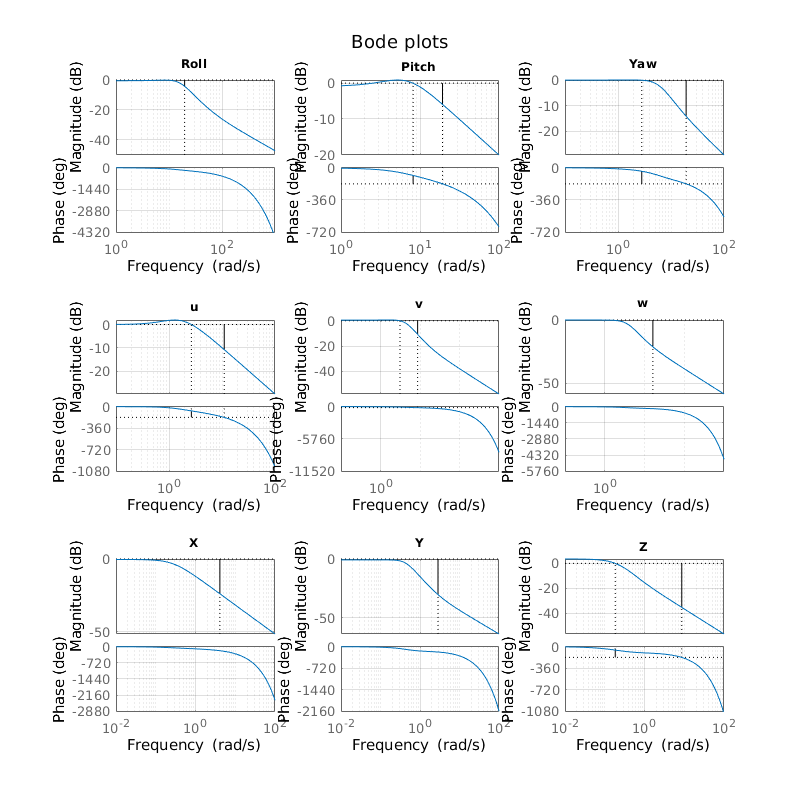

phaseResultTable = [];
for i = 1:dataSize
    phaseResultTable(i,1) = phaseResult{i}(1);
    phaseResultTable(i,2) = phaseResult{i}(2);
    phaseResultTable(i,3) = phaseResult{i}(3);
    phaseResultTable(i,4) = phaseResult{i}(4);
    phaseResultTable(i,5) = phaseResult{i}(5);
end

figure(10)
clf
set(gcf,'Position',[10 10 800 800])
for i = 1:dataSize
    sys = tf(tfData{i}.Num,tfData{i}.Den,'ioDelay',tfData{i}.Delay);
    subplot(3,3,i)
    hold on
    margin(sys)
    grid on
    title(dataName{i},'fontsize',14)
end
sgtitle('Bode plots') 
hold off

Frequency response is calculated using 'margin' function provided by MATLAB. For further detail, please refer to the following document.

[Link : Margin function explanation](https://kr.mathworks.com/help/control/ref/margin.html?searchHighlight=margin&s_tid=srchtitle)

columns = {'Gain Margin','Phase Margin','BandWidth'};
rows = {'Roll','Pitch','Yaw','u','v','w','X','Y','Z'};
T = table(phaseResultTable(:,1),phaseResultTable(:,2),phaseResultTable(:,5),'Rownames',rows);
T.Properties.VariableNames = columns

T = 9×3 table
             Gain Margin    Phase Margin    BandWidth
             ___________    ____________    _________

    Roll       1.6113             Inf         18.624 
    Pitch      1.9802           92.91         14.991 
    Yaw        5.0872          140.09         6.6292 
    u          3.4593          109.52         4.2125 
    v          3.4674          101.76         4.6558 
    w          11.575             Inf         3.6542 
    X          15.581             Inf        0.27279 
    Y          33.005             Inf        0.44507 
    Z          56.836          122.75        0.16573 


## Rotating Wing Vehicle flight Performance

There are various ways to evaluate the performance of the flying vehicle. However, there are frequently used performance indicators specialized for rotating wing aircrafts; TRC, Heaved response and axis coupling characteristics. Since quadrotors are basically a type of rotating wing vehicle, these indicators are suggested in this section. For further details, please refer to CoDPAD document.

rows = {'TRC_u';'TRC_v';'Heave Response'};
M300 = [stepResult{4}.RiseTime;stepResult{5}.RiseTime;1/heaveTfResult.Den(2)];
table(M300,'Rownames',rows)

ans = 3×1 table
                       M300  
                      _______

    TRC_u             0.41125
    TRC_v             0.45583
    Heave Response     0.3381


## Disturbance Rejection Performance

This section is incomplete. Please disregard.

#### 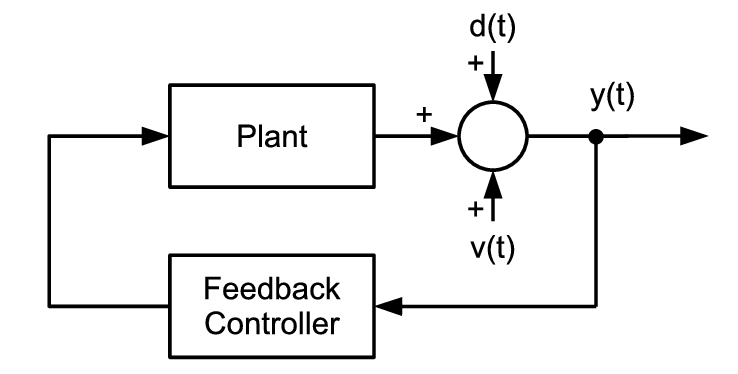

Response of this model can be calculated using,


$$y=\;\frac{\textrm{DG}}{\textrm{DGH}}C+\frac{G}{\textrm{DGH}}W$$


Tranfer function of latter part is called 'sensitivity transfer function' 


$$\frac{G}{\textrm{DGH}}$$


This segment tells us how the system reacts to disturbances. By drawing the Bode plot of this transfer function, DRB and DRP are acquired.

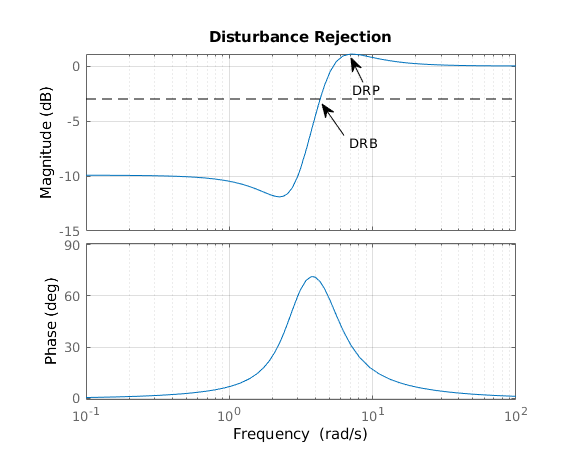

#### DRB

FutureWork

#### DRP

FutureWork

## State Holding Performance

This section analyzes the state maintenance performance which focuses on accuracy and vibration characteristics of the vehicle while performing a steady state flight (hovering, cruising). Error characteristic analysis utilizes statistical method based on the data acquired from the flight tests, and frequency analysis uses Fourier transform (FT) techniques.

% Generate random variable
stateSize = size(covResult.pos,1);
posHoldSampleData = mvnrnd(zeros(stateSize,1),covResult.pos,covSampleNum);
velHoldSampleData = mvnrnd(zeros(stateSize,1),covResult.vel,covSampleNum);
sampleVariable.pos = posHoldSampleData;
sampleVariable.vel = velHoldSampleData;
save('sampleVariable.mat','sampleVariable');

### Error Characteristic Analysis

Error characteristic is analyzed in two ways; std deviation calculation and spectral analysis. Std deviation is calculated based on the data acquired in steady state (posHoldFlight - hovering, velHoldFlight - cruising) flight. Spectral analysis also utilizes the same dataset, and performs FFT(Fast Fourier Transform) to calculate the PSD(Power Spectral Density). Std deviation and PSD results for each state variables (from attitude rate to position) are shown in this sub-section.

#### Rate error analysis

Std Deviation

columns = {'posHold','velHold'};
rows = {'p','q','r'};
T = table(covResult.posHoldStd(1:3)',covResult.velHoldStd(1:3)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
         posHold    velHold
         _______    _______

    p    3.5658     10.611 
    q    6.6088     6.2154 
    r      2.03     2.0375 


PSD

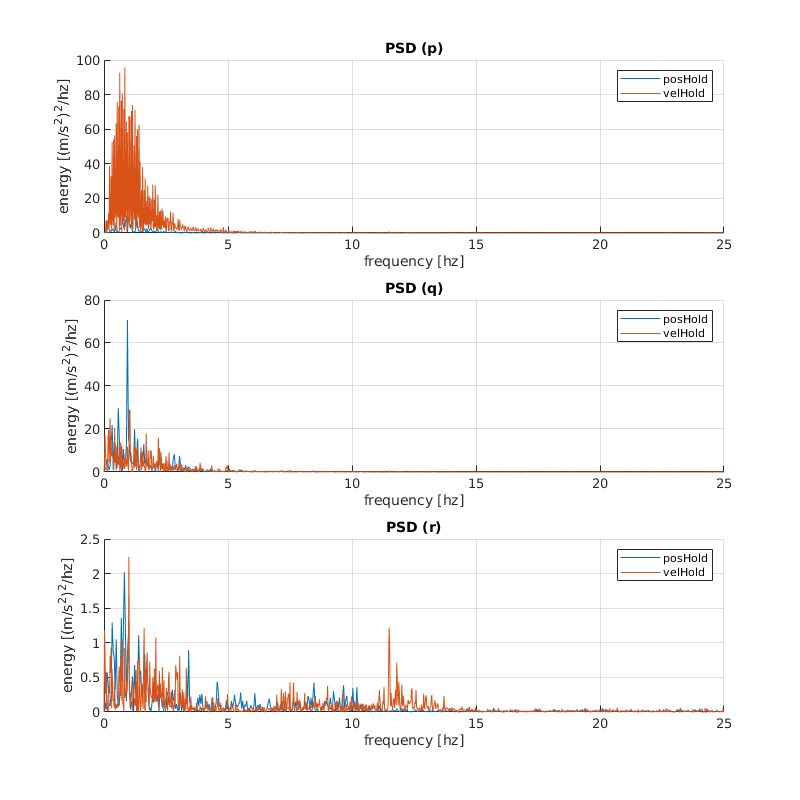

figure(5)
clf
subplot(3,1,1)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{1}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{1}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
title('PSD (p)')
grid on

subplot(3,1,2)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{2}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{2}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
title('PSD (q)')
grid on

subplot(3,1,3)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{3}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{3}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
grid on
title('PSD (r)')

set(gcf,'Position',[10 10 800 800])

#### Attitude error analysis

Standard deviation

rows = {'Roll','Pitch','Yaw'};
T = table(covResult.posHoldStd(4:6)',covResult.velHoldStd(4:6)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
              posHold      velHold 
             _________    _________

    Roll       0.01491     0.052747
    Pitch     0.024474     0.016496
    Yaw      0.0058191    0.0032985


PSD

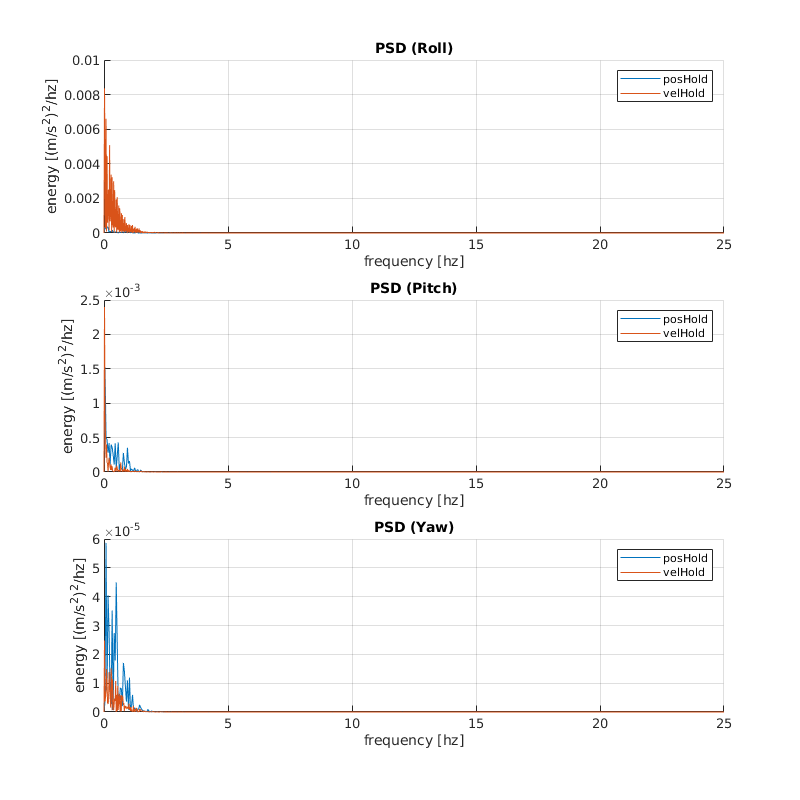

figure(6)
clf
subplot(3,1,1)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{4}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{4}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
title('PSD (Roll)')
grid on

subplot(3,1,2)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{5}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{5}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
title('PSD (Pitch)')
grid on

subplot(3,1,3)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{6}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{6}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
grid on
title('PSD (Yaw)')
set(gcf,'Position',[10 10 800 800])

#### Velocity error analysis

Standard deviation

rows = {'u','v','w'};
T = table(covResult.posHoldStd(7:9)',covResult.velHoldStd(7:9)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
         posHold     velHold 
         ________    ________

    u    0.065994    0.034084
    v    0.034899     0.90461
    w    0.039506    0.077043


PSD

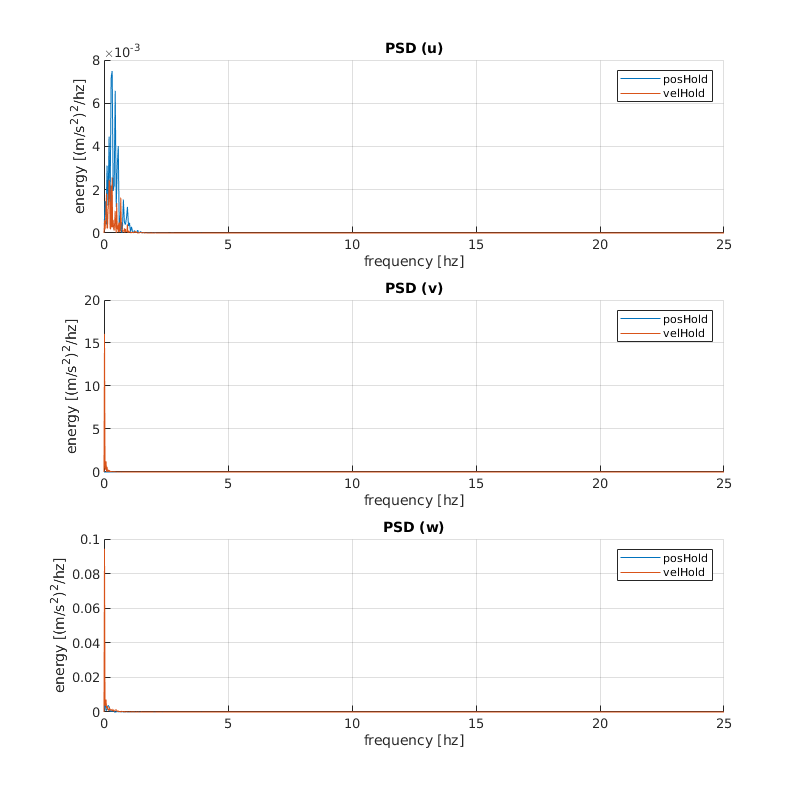

figure(7)
clf
subplot(3,1,1)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{7}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{7}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
title('PSD (u)')
grid on

subplot(3,1,2)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{8}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{8}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
title('PSD (v)')
grid on

subplot(3,1,3)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{9}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{9}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
grid on
title('PSD (w)')
set(gcf,'Position',[10 10 800 800])

#### Position error analysis

Standard deviation

rows = {'X','Y','Z'};
T = table(covResult.posHoldStd(10:12)',covResult.velHoldStd(10:12)','Rownames',rows);
T.Properties.VariableNames = columns

T = 3×2 table
         posHold     velHold
         ________    _______

    X     0.22881    0.21838
    Y    0.070293     6.5402
    Z    0.040012    0.73015


**Ignore Y stdDev for velHold result*

*PSD*

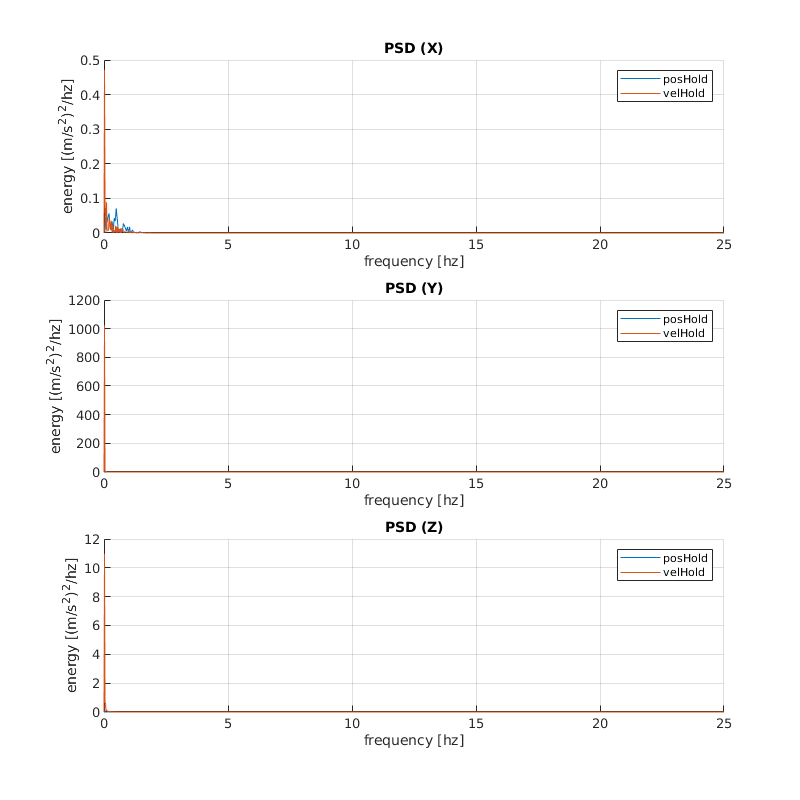

figure(8)
clf
subplot(3,1,1)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{10}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{10}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
title('PSD (X)')
grid on

subplot(3,1,2)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{11}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{11}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
title('PSD (Y)')
grid on

subplot(3,1,3)
hold on
plot(covResult.posHoldFreq{1}.freq,covResult.posHoldFreq{12}.psd);
plot(covResult.velHoldFreq{1}.freq,covResult.velHoldFreq{12}.psd);
legend('posHold','velHold')
xlabel('frequency [hz]')
ylabel('energy [(m/s^2)^2/hz]')
grid on
title('PSD (Z)')
set(gcf,'Position',[10 10 800 800])

### Combinatorial Error Distribution Analysis

There are several performance factors that requires combination of multiple state variables in order to be analyzed. However, combination of multiple state variables requires consideration of correlation between the variables. In this sub-section, bivariate analysis is performed for several cases involving two state variables; which may give some insight for the performance of the vehicle. The result is shown below.

#### qr error distribution

qr error distribution gives an insight of how steadily the vehicle can aim specific point. The more qr error distribution, the lower vividness we can expect from the body-fixed payloads.

xIdx = 2;
yIdx = 3;
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'pos');
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'vel');
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [dps^2]'];
disp(A);

90% posHold confidence area is 194.2152 [dps^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [dps^2]'];
disp(A);

90% velHold confidence area is 183.2717 [dps^2]


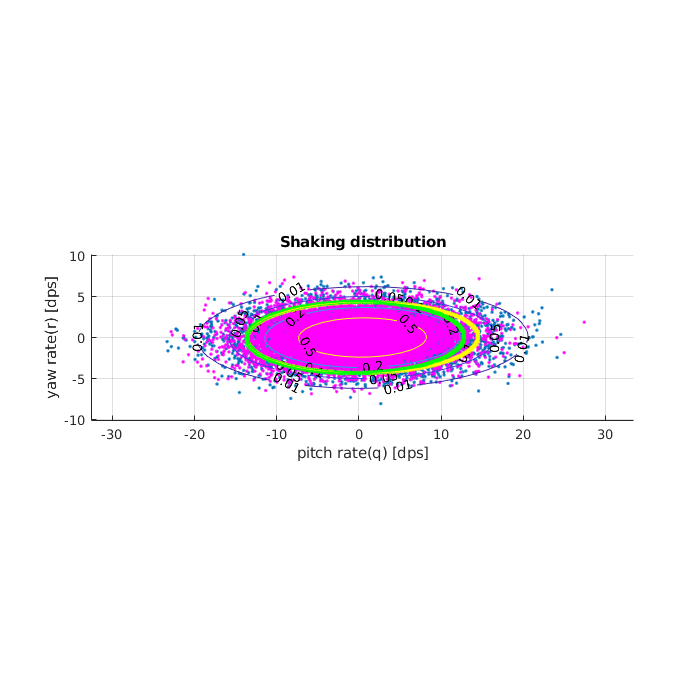

posEdgeIdx = convhull(pos_peripheral);
velEdgeIdx = convhull(vel_peripheral);

figure(1)
clf
hold on
plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
plot(vel_peripheral(velEdgeIdx,1),vel_peripheral(velEdgeIdx,2),'g-')
axis equal
title('Shaking distribution')
xlabel('pitch rate(q) [dps]')
ylabel('yaw rate(r) [dps]')
hold off
set(gcf,'Position',[10 10 700 700])

#### PY error distribution 

PY error distribution contributes to the pointing accuracy of the vehicle. It may provide insight into how accurately (different from steadiness) the vehicle can aim at specific target points. The less the PY error, the more accurateness we can expect from the vehicle.

xIdx = 5;
yIdx = 6;
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'pos');
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'vel');
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [deg^2]'];
disp(A);

90% posHold confidence area is 0.0020518 [deg^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [deg^2]'];
disp(A);

90% velHold confidence area is 0.00072562 [deg^2]


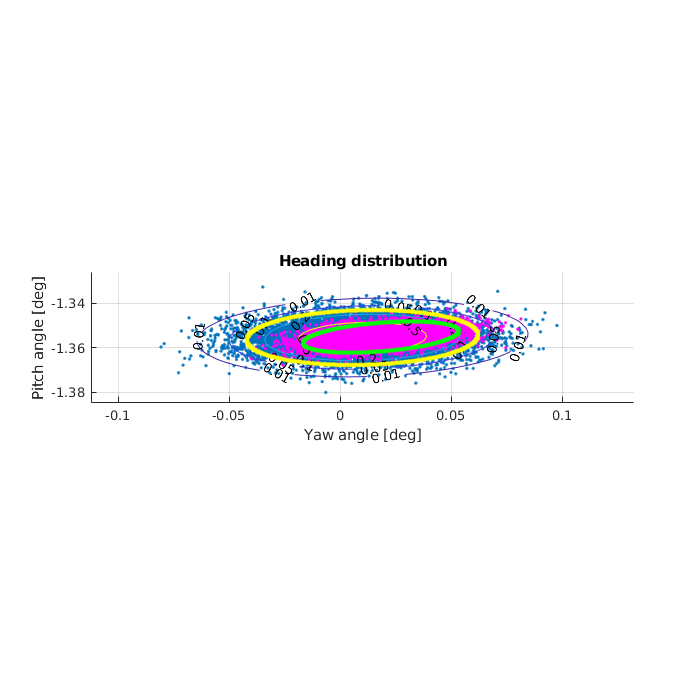

posEdgeIdx = convhull(pos_peripheral);
velEdgeIdx = convhull(vel_peripheral);

figure(2)
clf
hold on
plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
plot(vel_peripheral(velEdgeIdx,1),vel_peripheral(velEdgeIdx,2),'g-')
axis equal
title('Heading distribution')
xlabel('Yaw angle [deg]')
ylabel('Pitch angle [deg]')

set(gcf,'Position',[10 10 700 700])

#### RP error distribution 

RP error symbolizes horizontal attitude stabilization performance during steady-state flight. The less the RP error distribution, the more stable attitude the vehicle maintains. However, this value does not guarantee the position or velocity accuracy.

xIdx = 4;
yIdx = 5;
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'pos');
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'vel');
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [deg^2]'];
disp(A);

90% posHold confidence area is 0.0051609 [deg^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [deg^2]'];
disp(A);

90% velHold confidence area is 0.012569 [deg^2]


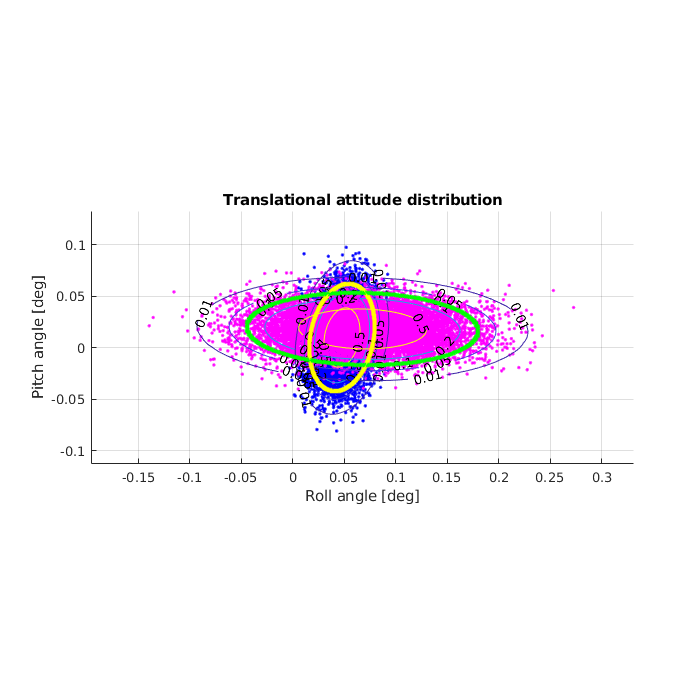

posEdgeIdx = convhull(pos_peripheral);
velEdgeIdx = convhull(vel_peripheral);

figure(3)
clf
hold on
plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'b.');
plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
contour(vel_X,vel_Y,vel_out/vel_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')

grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
plot(vel_peripheral(velEdgeIdx,1),vel_peripheral(velEdgeIdx,2),'g-')
axis equal
title('Translational attitude distribution')
xlabel('Roll angle [deg]')
ylabel('Pitch angle [deg]')
hold off
set(gcf,'Position',[10 10 700 700])

#### XY error distribution

XY error distribution directly measures the ability of the vehicle to maintain position during hovering flight. This measure only applies to hovering state, thus vehHold result is neglected in this section.

xIdx = 10;
yIdx = 11;
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'pos');
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(xIdx,yIdx,confidence,covResult,sampleVariable,'vel');
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [m^2]'];
disp(A);

90% posHold confidence area is 0.11276 [m^2]


A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [m^2]'];
disp(A);

90% velHold confidence area is 17.9116 [m^2]


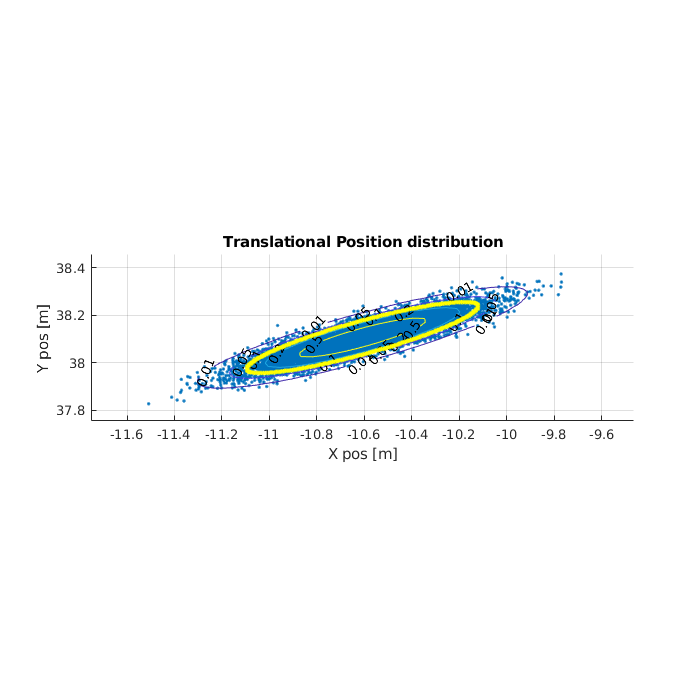

posEdgeIdx = convhull(pos_peripheral);
% velEdgeIdx = convhull(vel_peripheral);
figure(4)
clf
hold on
plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
% plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',5)
plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
% plot(vel_peripheral(velEdgeIdx,1),vel_peripheral(velEdgeIdx,2),'g-')
axis equal
title('Translational Position distribution')
xlabel('X pos [m]')
ylabel('Y pos [m]')
hold off

set(gcf,'Position',[10 10 700 700])

## Function definition - reference

Functions used in this livescript.

function [confidence_area,out,maxPdf,peripheral,X,Y] = multiVariateAnalysis(n,m,confidence,covResult,sampleVariable,mode)
% Internal parameters : DO NOT TOUCH
global calcDensity
level = 1-confidence;
zRange = 5;
cumulated = 0;
index = [];
peripheral = [];
density = calcDensity;

% calculate maxpdf
if(mode == 'pos')
    mu_x = covResult.posHoldMean(n);
    mu_y = covResult.posHoldMean(m);
    std_x = covResult.posHoldStd(n);
    std_y = covResult.posHoldStd(m);
    covar = covResult.pos(n:m,n:m);
elseif(mode == 'vel')
    mu_x = covResult.velHoldMean(n);
    mu_y = covResult.velHoldMean(m);
    std_x = covResult.velHoldStd(n);
    std_y = covResult.velHoldStd(m);
    covar = covResult.vel(n:m,n:m);
end

maxPdf = mvnpdf([mu_x mu_y],[mu_x mu_y],covar);
thres = level * maxPdf;

% distribution data for plotting
[X,Y] = meshgrid(linspace(mu_x-std_x*zRange,mu_x+std_x*zRange,50),linspace(mu_y-std_y*zRange,mu_y+std_y*zRange,50));
out = BiNorm(X,Y,[mu_x;mu_y],covar);

% distribution data for prob. calc.
xGrid = linspace(mu_x-zRange*std_x,mu_x+zRange*std_x,density);
yGrid = linspace(mu_y-zRange*std_y,mu_y+zRange*std_y,density);
xGrid(end) = [];
yGrid(end) = [];
xGridSize = xGrid(2)-xGrid(1);
yGridSize = yGrid(2)-yGrid(1);
gridArea = xGridSize * yGridSize;

for i = xGrid
    for j = yGrid
        if mvnpdf([i j],[mu_x mu_y],covar) >= thres
            cumulated = cumulated + mvncdf([i j],[i+xGridSize j+yGridSize],[mu_x mu_y],covar);
            index = vertcat(index,[i,j]);
        end
    end
end

% cumulated % for verification. This value must be equal to 'confidence' param.

for i = 1:length(index)
    if boxed(i,index,xGridSize,yGridSize)
        peripheral = vertcat(peripheral,index(i,:));
    end
end

confidence_area = length(index) * gridArea;
end

function flag = boxed(n,index,xGridSize,yGridSize)
x = index(n,1); y = index(n,2);
right = 0; left = 0; up = 0; down = 0;
flag = 0;

if isempty(find(abs(index(:,1)-(x+xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    right = 1;
end
if isempty(find(abs(index(:,1)-(x-xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    left = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y+yGridSize)) < yGridSize/2,1))
    up = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y-yGridSize)) < yGridSize/2,1))
    down = 1;
end

if up || down || right || left
    flag = 1;
end

end